%Regelkarten für eine für USB-Geschwindigkeit, Toleranz
%19.6 bis 20.4
data=readtable('USB.xlsx')

data = 10×5 table
    Var1    Anna     Benni     Michael     Jan 
    ____    _____    ______    _______    _____

      1     19.71    17.995    17.387     18.45
      2     19.92     18.41     16.96     18.88
      3      19.5     18.73    17.639     18.88
      4      19.5     18.42    16.648     18.88
      5     20.34     18.31    18.541     18.87
      6      19.5     18.31    18.024     18.66
      7     19.71    18.515    18.553     18.87
      8      19.5     18.12    17.675     19.08
      9     19.51    17.885    18.169     19.08
     10      19.5    17.575    16.747     19.09


%data2=readtable('USB2.xlsx')
%data(:,2:6).Variables=120+1.25*randn(21,5);

%Verschiedene Regelkarten
%igure(2)
%Einzelwertkarte
specLow = 16

specLow = 16

specHigh = 30

specHigh = 30

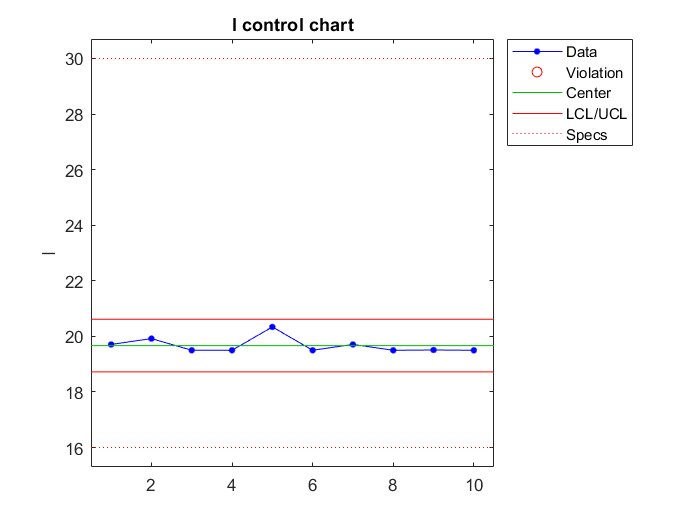

stats_i2 = struct with fields:
        n: [10×1 double]
     mean: [10×1 double]
        i: [10×1 double]
       mr: [10×1 double]
       mu: 19.6690
    sigma: 0.3160


plot_i2 = struct with fields:
    pts: [10×1 double]
     cl: [10×1 double]
    lcl: [10×1 double]
    ucl: [10×1 double]
     se: [10×1 double]
      n: [10×1 double]
    ooc: [10×1 logical]


%[stats_i2,plot_i2]=controlchart(data(:,2:5).Variables,data.Var1,"charttype","i","specs",[specLow specHigh])
grid on
[stats_i2,plot_i2]=controlchart(data(:,2:2).Variables,data.Var1,"charttype","i","specs",[specLow specHigh])

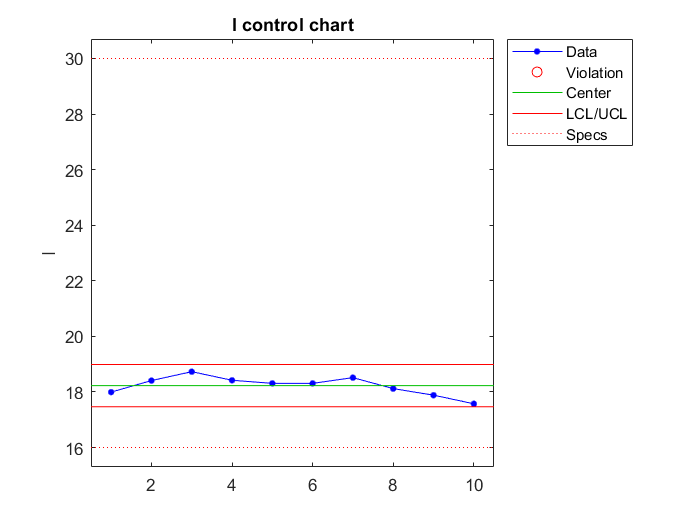

stats_i2 = struct with fields:
        n: [10×1 double]
     mean: [10×1 double]
        i: [10×1 double]
       mr: [10×1 double]
       mu: 18.2270
    sigma: 0.2537


plot_i2 = struct with fields:
    pts: [10×1 double]
     cl: [10×1 double]
    lcl: [10×1 double]
    ucl: [10×1 double]
     se: [10×1 double]
      n: [10×1 double]
    ooc: [10×1 logical]


[stats_i2,plot_i2]=controlchart(data(:,3:3).Variables,data.Var1,"charttype","i","specs",[specLow specHigh])

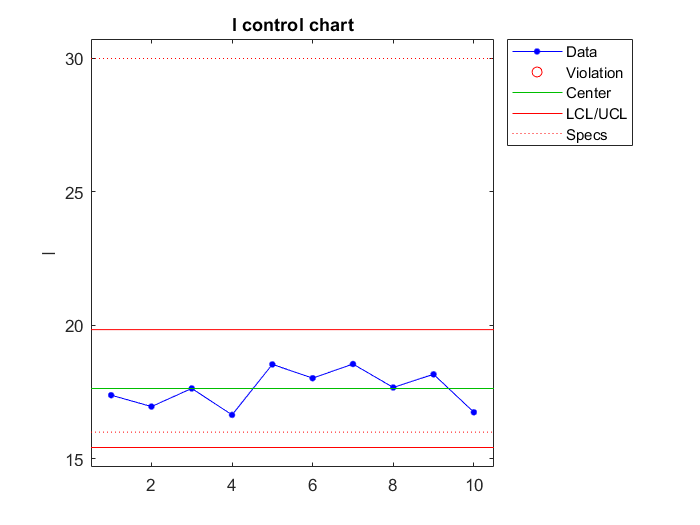

stats_i2 = struct with fields:
        n: [10×1 double]
     mean: [10×1 double]
        i: [10×1 double]
       mr: [10×1 double]
       mu: 17.6343
    sigma: 0.7366


plot_i2 = struct with fields:
    pts: [10×1 double]
     cl: [10×1 double]
    lcl: [10×1 double]
    ucl: [10×1 double]
     se: [10×1 double]
      n: [10×1 double]
    ooc: [10×1 logical]


[stats_i2,plot_i2]=controlchart(data(:,4:4).Variables,data.Var1,"charttype","i","specs",[specLow specHigh])

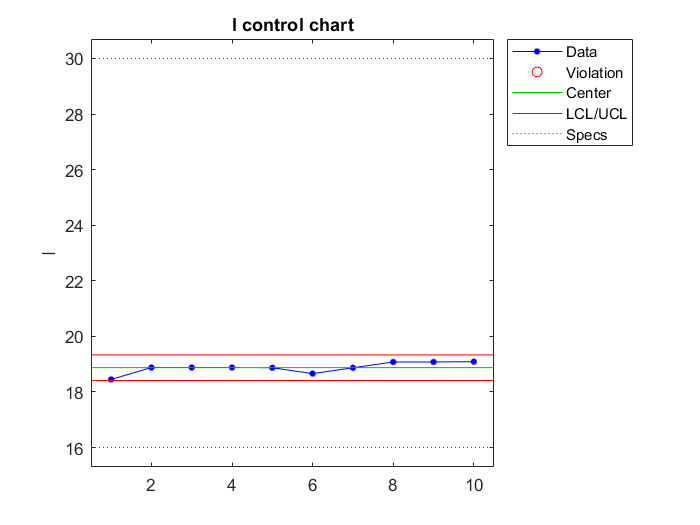

stats_i2 = struct with fields:
        n: [10×1 double]
     mean: [10×1 double]
        i: [10×1 double]
       mr: [10×1 double]
       mu: 18.8740
    sigma: 0.1533


plot_i2 = struct with fields:
    pts: [10×1 double]
     cl: [10×1 double]
    lcl: [10×1 double]
    ucl: [10×1 double]
     se: [10×1 double]
      n: [10×1 double]
    ooc: [10×1 logical]


[stats_i2,plot_i2]=controlchart(data(:,5:5).Variables,data.Var1,"charttype","i","specs",[specLow specHigh])

%data2
%[stats_i2,plot_i2]=controlchart(data2(:,2:11).Variables,data2.Var1,"charttype","i","specs",[specLow specHigh])

cp_Anna=capability(data(:,2).Variables,[specLow specHigh])

cp_Anna = struct with fields:
       mu: 19.6690
    sigma: 0.2758
        P: 1
       Pl: 1.1245e-40
       Pu: 2.4358e-307
       Cp: 8.4596
      Cpl: 4.4341
      Cpu: 12.4852
      Cpk: 4.4341


cp_Benni=capability(data(:,3).Variables,[specLow specHigh])

cp_Benni = struct with fields:
       mu: 18.2270
    sigma: 0.3379
        P: 1.0000
       Pl: 2.1992e-11
       Pu: 3.2462e-266
       Cp: 6.9046
      Cpl: 2.1967
      Cpu: 11.6126
      Cpk: 2.1967


cp_Michael=capability(data(:,4).Variables,[specLow specHigh])

cp_Michael = struct with fields:
       mu: 17.6343
    sigma: 0.6977
        P: 0.9904
       Pl: 0.0096
       Pu: 1.4015e-70
       Cp: 3.3442
      Cpl: 0.7808
      Cpu: 5.9076
      Cpk: 0.7808


cp_Jan=capability(data(:,5).Variables,[specLow specHigh])

cp_Jan = struct with fields:
       mu: 18.8740
    sigma: 0.1992
        P: 1
       Pl: 1.7908e-47
       Pu: 0
       Cp: 11.7116
      Cpl: 4.8085
      Cpu: 18.6148
      Cpk: 4.8085



std_Anna = std(data.Anna)

std_Anna = 0.2758

std_Benni = std(data.Benni)

std_Benni = 0.3379

std_Michael = std(data.Michael)

std_Michael = 0.6977

std_Jan = std(data.Jan)

std_Jan = 0.1992


% cpk = 0.4(Anna), 0.2(Benni), -0.1(Michael), 1.4(Jan). 
% Alle Prozesse sind beherrscht (Da innerhalb von UCL und OCL).
% In Halbleiterindustrie muss cpk >= 1,3 sein.
% Nur Jans Prozess ist für die HLI fähig.


%XBAR-Chart mit s und R 
[stats_xs,plot_xs]=controlchart(data(:,2:5).Variables,data.Var1,'charttype',{'xbar' 's'})

stats_xs = struct with fields:
     mean: [10×1 double]
      std: [10×1 double]
        n: [10×1 double]
    range: [10×1 double]
       mu: 18.6011
    sigma: 1.0000


plot_xs = 1×2 struct array with fields:
    pts
    cl
    lcl
    ucl
    se
    n
    ooc


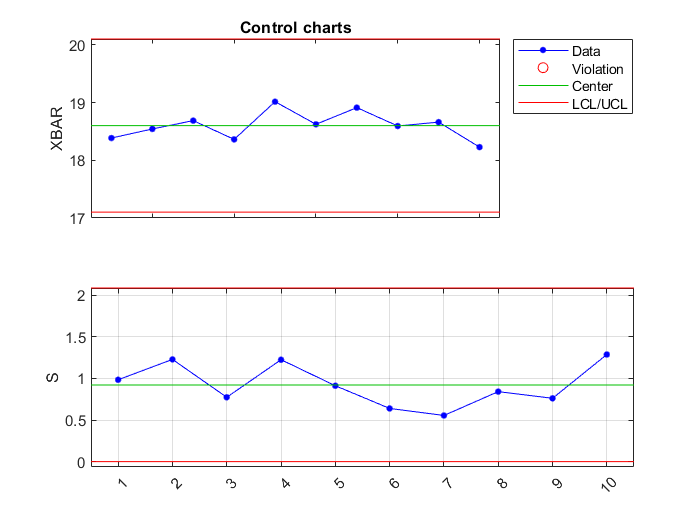

% aus XBAR s kann man erkennen, zu welchem Zeitpunkt die größte Streuung
% war
grid on
axes=gca;
axes.XTickLabelRotation=45;


[stats_xr,plot_xr]=controlchart(data(:,2:5).Variables,data.Var1,'charttype',{'xbar' 'r'})

stats_xr = struct with fields:
     mean: [10×1 double]
      std: [10×1 double]
        n: [10×1 double]
    range: [10×1 double]
       mu: 18.6011
    sigma: 1.0000


plot_xr = 1×2 struct array with fields:
    pts
    cl
    lcl
    ucl
    se
    n
    ooc


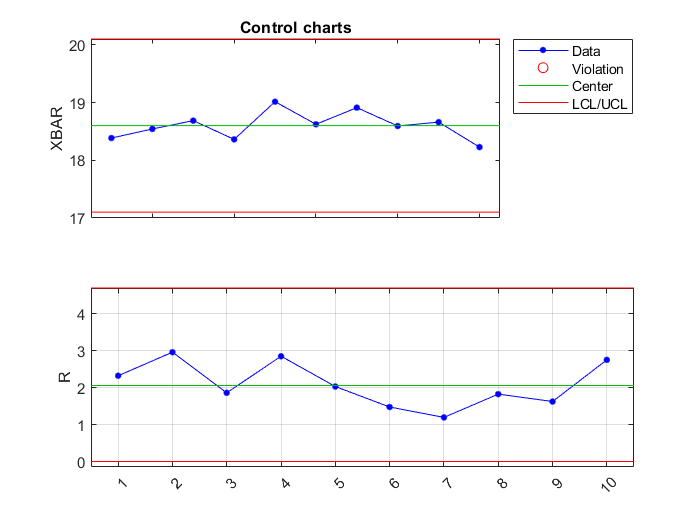

grid on
axes=gca;
axes.XTickLabelRotation=45;

%Darstellung Histogramme und qq-Plots zu Mean und sigma bzw. Varianz, Test
%auf Normalverteilung
sigma=std(data(:,2:5).Variables')

sigma =     0.9845    1.2293    0.7742    1.2254    0.9126    0.6396    0.5553    0.8419    0.7617    1.2885


variance=var(data(:,2:5).Variables')

variance =     0.9693    1.5111    0.5995    1.5015    0.8328    0.4091    0.3084    0.7088    0.5802    1.6603


mean_daten=mean(data(:,2:5).Variables')

mean_daten =    18.3855   18.5425   18.6872   18.3620   19.0153   18.6235   18.9120   18.5938   18.6610   18.2280


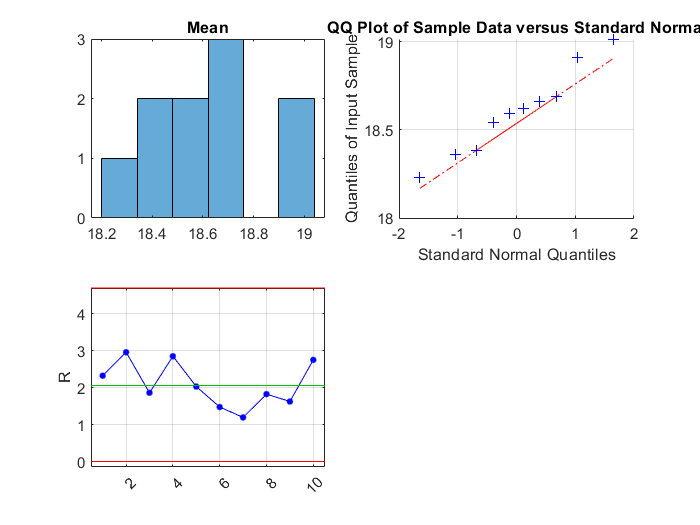

subplot(2,2,1)
histogram(mean_daten,round(2*sqrt(10),0))
title("Mean")
subplot(2,2,2)
qqplot(mean_daten)
grid on

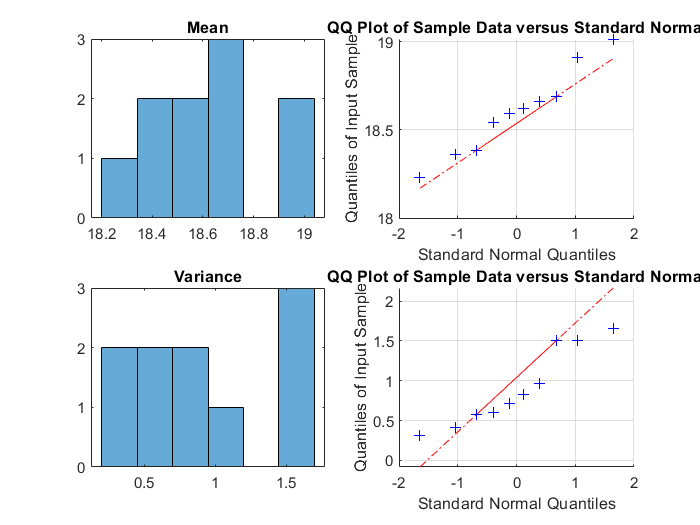

subplot(2,2,3)
histogram(variance,round(2*sqrt(10),0))
title("Variance")
%histogram(sqrt(variance),round(2*sqrt(21),0))
%title("sigma")
subplot(2,2,4)
qqplot(variance)
grid on

[h_mean,p_mean]=adtest(mean_daten)

h_mean = logical
   0


p_mean = 0.8092

[h_var,p_var]=adtest(variance)

h_var = logical
   0


p_var = 0.2044


% Anderson Darlington Test sagt, dass H0 angenommen wird und somit Daten
% normalverteilt sind


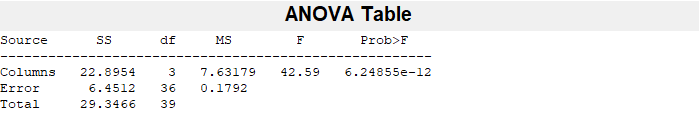

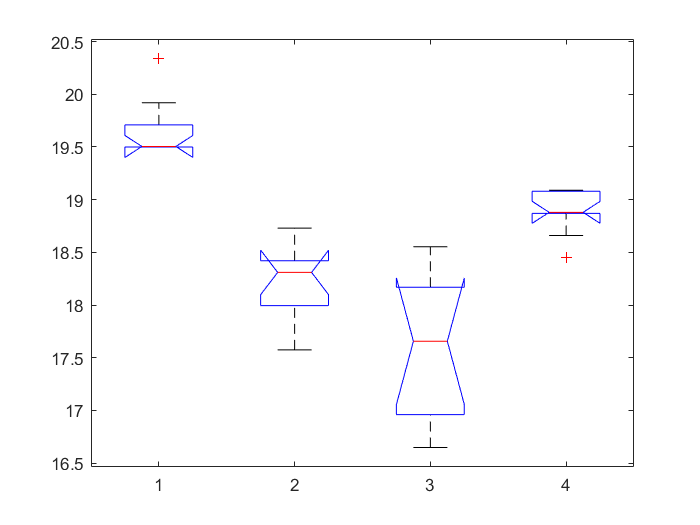

p = 6.2486e-12

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[22.8954]}    {[ 3]}    {[  7.6318]}    {[ 42.5879]}    {[6.2486e-12]}
    {'Error'  }    {[ 6.4512]}    {[36]}    {[  0.1792]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[29.3466]}    {[39]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: [4×1 char]
         n: [10 10 10 10]
    source: 'anova1'
     means: [19.6690 18.2270 17.6343 18.8740]
        df: 36
         s: 0.4233


%ANOVA nur machen, wenn Normalverteilt
[p,tbl,stats] = anova1(data(:,2:5).Variables)

%Mittelwerte sind nicht gleich zwischen den Messreihen


sigsum = sum(sigma)

sigsum = 9.2130

22.8954 / sigsum

ans = 2.4851

% > 1 -> H0 ablehnen
